# Linear Regression:

The data in the accompanying table relate heart rate at rest Y to kilograms body weight X.

clear all
X = [90, 86, 67, 89, 81, 75]

X =     90    86    67    89    81    75


Y = [62, 45, 40, 55, 64, 53]

Y =     62    45    40    55    64    53


## A: Graph these data. Does it appear that there is a linear relationship between body weight and heart rate at rest?

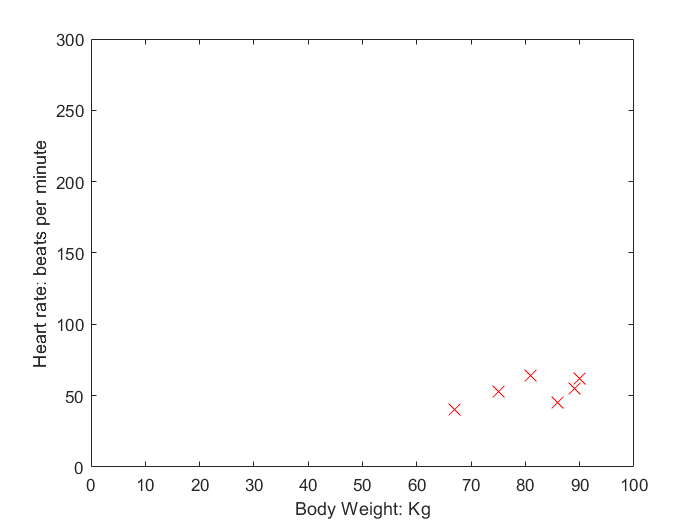

plot_data(X,Y)

R: Yes, a direct linear relationship.

## A: Compute a,b and write the regression equation for these data. Plot the regression line on the graph. Interpret the estimated regression coefficients.

close all
new_X = [ones(1,size(X,2)); X]'

new_X =      1    90
     1    86
     1    67
     1    89
     1    81
     1    75


theta = pinv(new_X' * new_X) *new_X' * Y'

theta =     4.7990
    0.5947


points = linspace(min(X)-30,max(X)+30,10);

line = predict(points, theta);

J = cost_function(X, Y', theta); %% error

J = 2.5461e-25

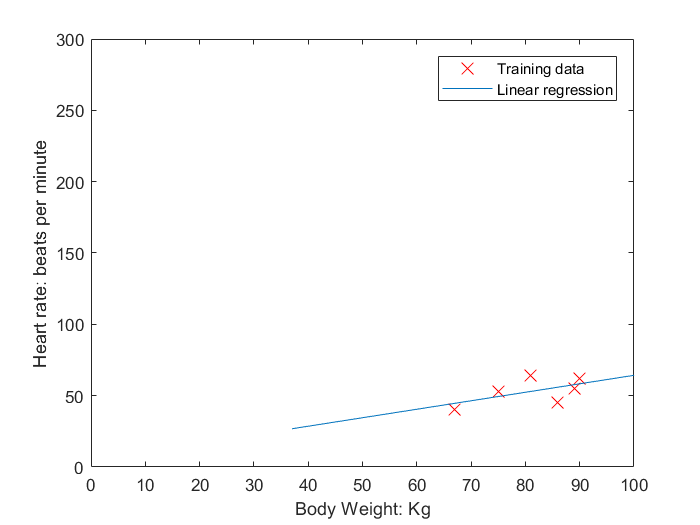


plot_data(X, Y);hold on
plot(points,line, '-');hold off
legend('Training data', 'Linear regression')

Theta $\theta=(4.799; 0.5947)$ are the coeficients of the Hypotesis $h(x,\theta) = \theta_0 * x_0 + \theta_1 * x_1$ being $x_0$ the bias term = 1. This hypotesis represent a linear equation so $\theta_0$ is the point where the line cuts the y axis. $\theta_1$ is a factor that represents how important is the feature X.